%https://docs.google.com/spreadsheets/d/1YDlMPtYdSVsHdrFVt8_7MTUF_CIstmmzhMWmsxN5lXA/edit?usp=sharing
fileID = '1YDlMPtYdSVsHdrFVt8_7MTUF_CIstmmzhMWmsxN5lXA';
csvURL = ['https://docs.google.com/spreadsheets/d/' fileID '/export?format=csv'];

% 2) Download the CSV to a temporary local file:
tmpFile = [tempname, '.csv'];    % e.g. 'C:\Users\...\AppData\Local\Temp\xyz123.csv'
opts = weboptions('Timeout', 60);
websave(tmpFile, csvURL, opts);        % this fetches the entire CSV (all ~8 M rows)

% 3) Now read it with readmatrix:
M = readmatrix(tmpFile);

% 4) Delete the temp file if you want:
delete(tmpFile);

% 5) Check how many rows you got:
fprintf('Imported %d rows from Google Sheets CSV.\n', size(M,1));

Imported 8313984 rows from Google Sheets CSV.


y = M(:,1);      % assume the first (and only) column is your waveform
anyNaN  = any(isnan(y));      % true if there are any NaNs
anyInf  = any(isinf(y));      % true if there are any +Inf or -Inf
fprintf('anyNaN = %d, anyInf = %d\n', anyNaN, anyInf);

anyNaN = 0, anyInf = 0


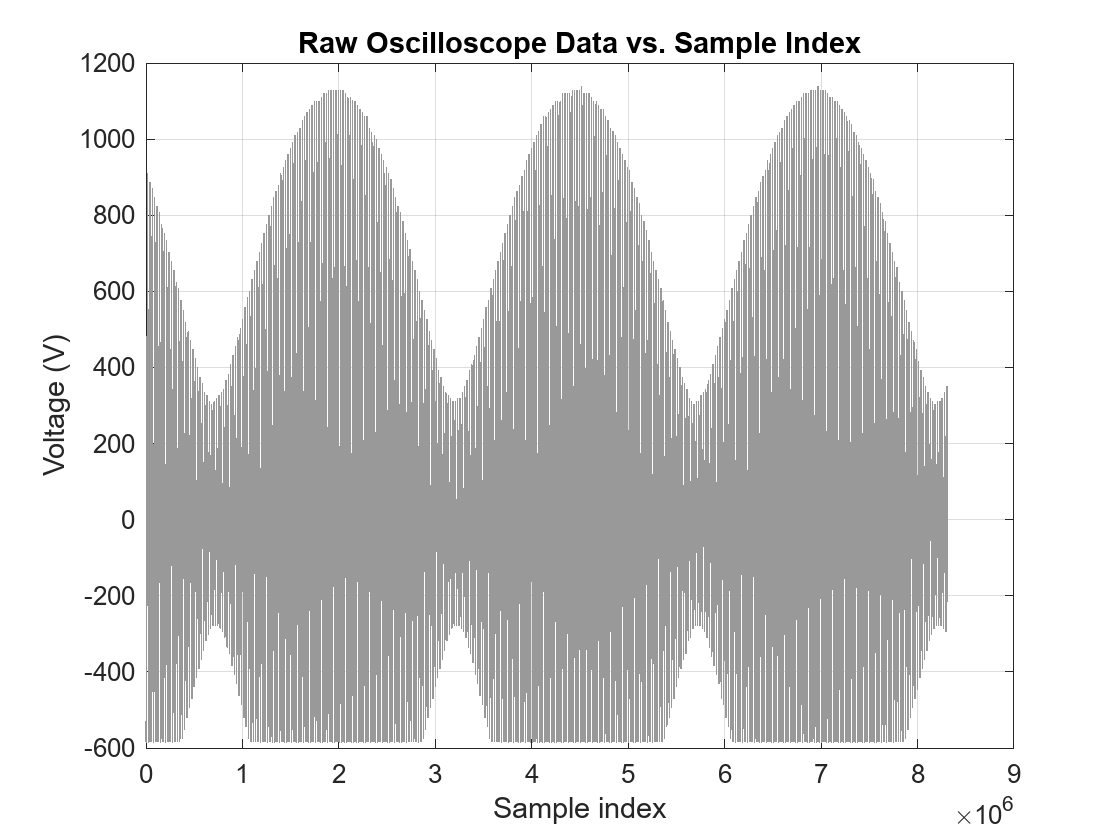

badIdx = isnan(y) | isinf(y);
if any(badIdx)
    warning('Dropping %d non‐finite samples before envelope.', sum(badIdx));
    y(badIdx) = [];   % deletes all NaN or Inf entries
    idx(badIdx) = []; % also remove the corresponding sample‐indices if you kept them
    N = numel(y);     
    idx = (1:N).';    % or re‐create index from scratch
end
%y = str2double(y)
% Number of samples:
N = numel(y);
idx = (1:N).';           % sample indices 1,2,…,N

figure;
plot(idx, y, 'Color', [0.6 0.6 0.6]);
xlabel('Sample index');
ylabel('Voltage (V)');
title('Raw Oscilloscope Data vs. Sample Index');
grid on;

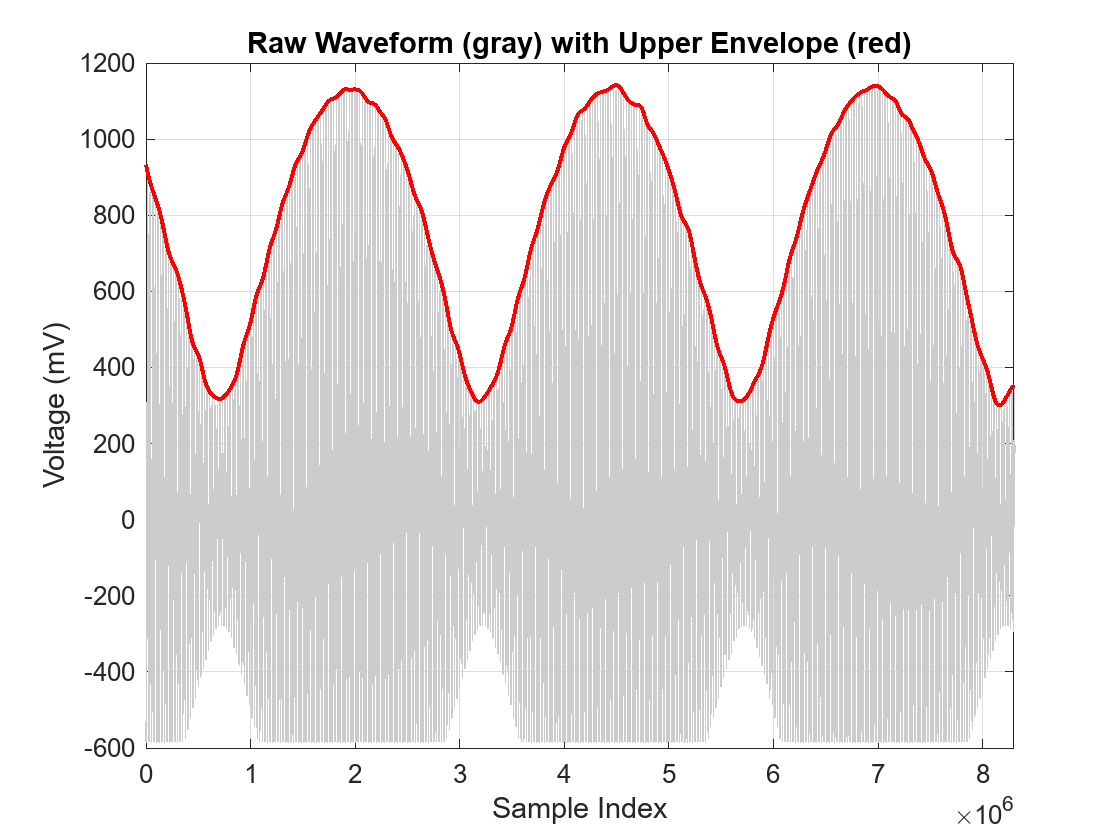

window = 50000;    
[upEnv, loEnv] = envelope(y, window, 'peak');
figure;
plot(idx, y,       'Color',[0.8 0.8 0.8]); hold on;
plot(idx, upEnv,   'r', 'LineWidth', 1.5);
xlabel('Sample Index');
ylabel('Voltage (mV)');
title('Raw Waveform (gray) with Upper Envelope (red)');
grid on;
xlim([   0           8.3e6 ]);   % zoom into first 2 million samples

% (You can change xlim to see the entire 8 million range if you like)

env_max = max(upEnv);
env_min = min(upEnv);

p2p     = env_max - env_min;
fprintf('Upper‐envelope peak-to-peak = %g mV\n', p2p);

Upper‐envelope peak-to-peak = 842.078 mV
